# `Wavelet Feature Generator`

Written by Rahul R. Birmiwal 2019. 

V2-Modified by Todd Schultz

This file produces a feature vector for each audio .wav file in the *DataExamplesV2* directory.With 118 audio signals there, it thus produces a 118 x D matrix of training data, with the rightmost column the output vector *y* appropriately labeled in {0,1}. 

The wavelet transform and its families rely on two key parameters: 

- The "mother" wavelet / wavelet family 

- The wavelet transform decomposition level  

We set these parameteres here: 

% Wavelet Parameters
waveletName = 'coif2';
waveletLevels = 5; 

Possible wavelet names and further information can be found here [https://www.mathworks.com/help/wavelet/ref/waveinfo.html](https://www.mathworks.com/help/wavelet/ref/waveinfo.html)

The maximum possible wavelet decomposition level, for a given wavelet family,  can be found here [https://www.mathworks.com/help/wavelet/ref/wmaxlev.html](https://www.mathworks.com/help/wavelet/ref/wmaxlev.html)

After much experimentation, we have set the most optimal wavelet family of choice to be the *Coiflet* wavelet with 2 vanishing moments, with 4 levels of decomposition used in the transform.  

## Basic Theory

### **Filter Bank Interpretation of the Discrete Wavelet Transform **

Given a mother wavelet function $\psi(t)$, the DWT uses sampled values of shifted and scaled versions of the mother wavelet, namely: 

$\psi_{j,k}(t) = \frac{1}{\sqrt{2^j}}\psi\left(\frac{t-k2^j}{2^j}\right)$ where *j* is the scaling parameters; *k* the shifting.

The *wavelet coefficient* of a signal *x(t)* is the prjection of *x(t)* onto the wavelet. For a signal *x *fit to length $2^N$, the coefficient at one of the nodes for a given scaling parameter and shifting is 


$$\gamma_{j,k}(t) = \int_{-\infty}^{\infty}x(t)\frac{1}{\sqrt{2^j}}\psi\left(\frac{t-k2^j}{2^j}\right)dt$$


Now with respect to the DWT, this equation, for a fixed scaling level *j*, can be viewed as the convolution of the original signal *x*(t) with reflected and shifted versions of the mother wavelet 

$h(\tau) = \frac{1}{\sqrt{2^j}}\psi\left(\frac{-\tau}{2^j}\right)$ sampled at points $\tau = 1, 2^j, 2^{2j}, ...., 2^N$. 

Let *h[n]* be the sampled version of the above, and similarly define a series *g[n]* produced similarly from the mother and child wavelets, then the Discrete Wavelet Transform can be computed in closed-form algorithm as follows. Here we consider one level of the DWT: 

Let the DWT of a signal x be *y[n]. *Then we define the "approximation coefficients" of the DWT to be the convolution of *x* and filter *g*, namely 


$$y[n] = (x* g)=\sum_{k=-\infty}^{\infty}x[k]g[n-k]$$


And simultaneously define the "detail coefficients" of the DWT to be the convolution of *x* with filter *h* (as defined above). 

The outputs of each of these "branches" of the filter-bank "binary tree" is then subsampled by a factor of 2 in accordance with Nyquist's Rule. This is precisely a level-1 DWT given mother wavelet $\psi$. 

It is easiest to visualize higher-level DWT using this binary tree analogy. Let the original signal be the root node of the tree, and convolutions with the low-pass filter *g* be the righthand branches; likewise the high-pass filter be the leftside branches. Then the level-*L* coefficients are computed in a recurrent fashion by applying this level-1 algorithm repeatedly to the outputs of righthand nodes of the tree, *L* times, and extracting the final coeffcients produced with the convolution with *h[n]*. 

Due to this structure, the frequencies of analysis/iinterest borne from the DWT lie on a dyadic/logarithmic scale. 

### **Discrete Wavelet Packet Transform**

The DWPT is another version of the wavelet transform. It's only difference to the DWT is that it produces a balanced binary tree of nodes -- the recurrence is applied to both branches of the tree, not just the righthand  branch. 

## Features Generated

We now discuss the features generated in this module. These are, for an *L* level transform and choice of mother wavelet: 

- Shannon Entropy of the terminal nodes of the *L*-level DWPT 

- Wavelet *variance *at each of the levels

- Subband statistics of the coefficients at each of the level

#### i. Shannon Entropy of the Discrete Wavelet Packet Transform 

For *k-th* coefficient of the *jth* node at the *i-th* level of the DWPT, let the wavelet energy be defined as 

$E_{i,j,k} = ||\gamma_{i,j,k}||^2$ and the total energy for a level is the sum over *k, *$E_{i,j}$. 

Define the probability energy of the kth node to be $p_{i,j,k} = \frac{E_{i,j,k}}{E_{i,j}$. Then the shannon entropy of the *jth* node at level *i *is: 

$SE_{i,j} = -\sum_{k=1}^{N}p_{i,j,k}*log(p_{i,j,k})$ where 

The helper function *shannonEntropy*.m is used to compute this features. 

#### ii. Wavelet Variance of the Time-Series Signal

 In "On Estimation of the Wavelet Variance" Donald P. Percival formalizes the concept of the "wavelet variance" -- a measure of how the variance of a real-valued stochastic process *Y* decomposes with respect to a scaling parameter $\lambda$. More formally, the Discrete Wavelet Transform provides mechanism for compactly regularizing the spectrum of *Y* at octave-band levels. Although the mathematics of this paper are extraordinarily advanced and beyond the scope of this project, the basic premise is that: 

For a given spectrum of the Y denoted $S_{Y}$, just as the Discrete *Fourier* Transform yields the estimator of $S_{Y}$ called the "periodogram" written: 


$$\hat{S_{Y}(\frac{j}{N}) = \frac{1}{N}\left|\sum_{t=1}^{N}(Y_{t}-\bar{Y})e^{-i2\pi*j/Nt}\right|^2$$
 

for an N length time-series, 

The DWT produces an estimator the wavelet variance 


$$\hat{v_{Y}}^2(\lambda):=\frac{1}{N}\sum_{t=1}^{0.5N/\lambda}D^2_{t, \lambda}$$


where the series *D* is related to the output of convolution of the signal *Y* with the wavelet filter *h[n]* as discussed previously scaled at lambda. 

In the paper, however, Percival makes the key connection of relating such variance to the spectrum of a real-valued stationary stochastic process $S_{Y}$, such that under most conditions 


$$\hat{v_{Y}}^2(\lambda) =2\int_{1/(4\lambda)}^{1/(2\lambda)}S_{Y}(f)df$$


thereby "summarises the information in the spectrum using just one value per octave frequency band and is particularly useful when the spectrum is relatively featureless within each octave band" (Percival 620). 

Estimates of the wavelet variance are numerically produced given maximal-overlap DWT. 

The MATLAB implementation of the methods in Percival's work come from the function's *modwtvar()*(https://www.mathworks.com/help/wavelet/ref/modwtvar.html). 

#### iii. Subband Statistics 

In [3] Tzanetakis, Essl, et. al discuss methods to classify non-speech audio signals and beat detection using the Discrete Wavelet Transform. In particular they highlight features generated from statistics about the coefficients in each dyadic sub-band. These are for a band level *j*: the mean of the absolute values of *jth*-level coefficients, standard deviation of *jth*-level coefficients, and vector of ratios between means between the *jth* and *jth + 1* subbands for *j = 1, 2, …, L. *

The Matlab helper function *subbandStatistics.m* is used to compute these features 

#### iv. Feature Vectors

For an audio signal, clean or contaminated, a feature vector is generated by concatenating the outputs of each of these three feature sets. 

#### v. Aside on PCA

The output of the Shannon Entropy feature vector produces many covariates. As a result Principal Component Analysis (PCA) was experimented with, and determined that projection of the entropy vector onto a 4-principal component subspace yielded close to the same performance at much faster computational complexity. As a result in creating the training data, as well as for arbitrary new signal classification, we project onto this subspace first. Namely, let the matrix *E *be the 118 x *P* matrix of entropy vectors per audio signal and the matrix *W* be the *P x 4* PCA matrix with 4 principal components. Then the output vector 1 x P from *shannonEntropy.m, *x*, *is multipled by *W, *such that *xW* is used as the feature vector for classification algorithms. 

## Usage

The below code produces a training data matrix titled *FinalWaveletFeatures_PCA_SS* which is a 118 x [length of concatenated feature vectors + 1] sized matrix where the last column is the output labels for classification. This matrix can be used directly into Matlab's Classification Learner App for machine learning work. 

With the coiflet2 wavelet with 4 levels of decomposition, this matrix and methodology for feature generation will yield ~92-99% accuracy for most algorithms, with a well-balanced confusion matrix. 

## Generate Features	

## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamples' directory. 

%save('FinalWaveletFeatures_PCA_SS_' + waveletName + "_L" + waveletLevels + '.mat');
% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesWavelets" + "_" + waveletName + "_Lvl" + waveletLevels + "NOHampel"; 

% Find data examples directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File descriptions
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

% Create pool of MATLAB workers
 %tic; parpool('local',2); toc


## Processing parameters

List and define processing parameters.

% processing type
type = "Wavelet";

% record or block duration (s)
tblock = 2;
featurefilename = featurefilename + "_T" + tblock; 

% fractional overlap between blocks, 0 <= foverlap <= 1
foverlap = 0.5;

% frequency limits for octave
freqlim = [30 20000];

% Signal to noise ratio
snrdB = 6;

## Signal files

Read in clean signal files. Store them in two cell arrays: 

- Store the full 1-D signal in x_1Dsignals

- Store the spectral reshaped signal in xBlockSignals

The different forms of a given signal need to be used together in wavelet signal processing 

% Loop over all signal files
xBlockSignals = cell(length(signalFiles),1);
fc = cell(length(signalFiles),1);
for ifile = 1:length(signalFiles)
    % Load file
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    % Apply Hampel Filter 
    % x = hampel(x); 
    
    
    xblock = spectralReshape(x,noverlap,nblock);
    %x_1Dsignals{ifile} = x; 
    xBlockSignals{ifile} = xblock';
end
xBlockSignals = cell2mat(xBlockSignals);

Now repeat the same process for contaminated signal files

% Make contamination signal assignments
% one contamination file index for each of the signal files
rng(42);
contaminationAssign = randi(length(contaminationFiles),1,length(signalFiles));

% Process signal files one at a time and add contamination signals
xcntm_blockSignals = cell(length(signalFiles),1);
%xcntm_1Dsignals = cell(length(signalFiles),1);
for ifile = 1:length(signalFiles)
    contaminationFilesLocal = contaminationFiles;
    % Load files
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    [n,fn] = audioread(fullfile(datadir,contaminationFilesLocal(contaminationAssign(ifile))));
    assert(fs == fn,'featureGenerator:UnequalSampleRates',...
        'Sample rates for the signal data and the contamination data are not equal.')
    
    
    % Adjust contamination signal length
    n = repmat(n,ceil(length(x)/length(n)),1);
    n = n(1:length(x));
    
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    % Apply Filter 
    % x = hampel(x);
    
    % Reshape into blocks
    xblock = spectralReshape(x,noverlap,nblock);
    n = spectralReshape(n,noverlap,nblock);
    
    % Super impose signal and noise together
    xblock = addNoise(xblock,n,snrdB);
    
    %Store them 
    %xcntm_1Dsignals{ifile} = x; 
    xcntm_blockSignals{ifile} = xblock';
end
xcntm_blockSignals = cell2mat(xcntm_blockSignals);

## Combine signal blocks

Combine the clean and contaminated signal blocks into a single signal block matrix. Also, create a response vector to track the known class of each signal block. 

% Combine signal blocks
xsignal = [xBlockSignals; xcntm_blockSignals];
xresponses = [false(size(xBlockSignals,1),1); true(size(xcntm_blockSignals,1),1)];

% Variable clean up
clear xcntm_blockSignals xBlockSignals xblock n x

#### Entropy Features 

Compute the Shannon entropy and reduce dimensionality with principal component analysis. 

% Compute entropy values for each signal block
tic
se = shannonEntropyV2(xsignal,waveletName,waveletLevels);
[~,sepca] = pca(se,'NumComponents',4);
toc

Elapsed time is 1591.906217 seconds.


#### Wavelet Variance Features 

tic
wVar = waveletVar(xsignal,waveletName,waveletLevels);
toc

Elapsed time is 395.616629 seconds.


#### Subband Statistics 

% Compute subband statistics
tic
if (waveletLevels > 2)
    subbandstats = subbandStatisticsV2(xsignal,waveletName,waveletLevels);
else 
    subbandstats = []; 
end
toc

Elapsed time is 25.451297 seconds.


## Assemble final features

%xfeatures = [sepca wVar subbandstats];
xfeatures = [se wVar subbandstats];
XTrain = [xfeatures xresponses];
% Clear variables to reduce file size
clear xsignal ifile 
save(fullfile(featuredir,featurefilename))

## References

- Tzanetakis, George & Essl, Georg & Cook, Perry. (2001). Audio Analysis using the Discrete Wavelet Transform. Proceedings of the Conference in Acoustics and Music Theory Applications. 318-323.

-  Li T, Zhou M. ECG Classification Using Wavelet Packet Entropy and Random Forests. *Entropy*. 2016; 18(8):285.

- Percival, Donald. (2012). On Estimation of the Wavelet Variance. Biometrika. 82. 10.1093/biomet/82.3.619.

### Neural Networks

Now explore the above feature set *xfeatures* with labels *xresponses* with respect to a basic one hidden layer feedfoward neural network. Below are the performance of roduct of network parameters results of networks containing 10, 64, and 100 nodes, using Bayesian Regularization and LR training method 

ypred = round(nn10lr_coif2T2L5hmpl(xfeatures)); 
acc = 100*(sum(ypred==xresponses)/numel(xresponses));
acc

acc = 90.7048

ypred = round(nn20lr_coif2T2L5hmpl(xfeatures)); 
acc = 100*(sum(ypred==xresponses)/numel(xresponses));
acc

acc = 95.7190


ypred = round(nn30lr_coif2T2L5hmpl(xfeatures)); 
acc = 100*(sum(ypred==xresponses)/numel(xresponses));
acc

acc = 92.8335

ypred = round(nn40lr_coifT2L5hmpl(xfeatures)); 
acc = 100*(sum(ypred==xresponses)/numel(xresponses));
acc

acc = 91.7928

load(fullfile('FeaturesWavelets_coif2_Lvl5_T2hmpl.mat'));

N = length(xfeatures);
xcell = mat2cell(xfeatures,[ones(1,N)]); 
ycell = (mat2cell(categorical(xresponses), [ones(1,N)]));
xcell_t = cellfun(@transpose, xcell, 'UniformOutput', false);
inputSize = 49;
numHiddenUnits = 100;
numClasses = 2;
lv =  lstmLayer(numHiddenUnits,'OutputMode','last'); 
lv.RecurrentWeights = randn([4*numHiddenUnits numHiddenUnits])*0.01;
layers = [ ...
    sequenceInputLayer(inputSize)
    lv 

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 49 dimensions
     2   ''   LSTM                    LSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

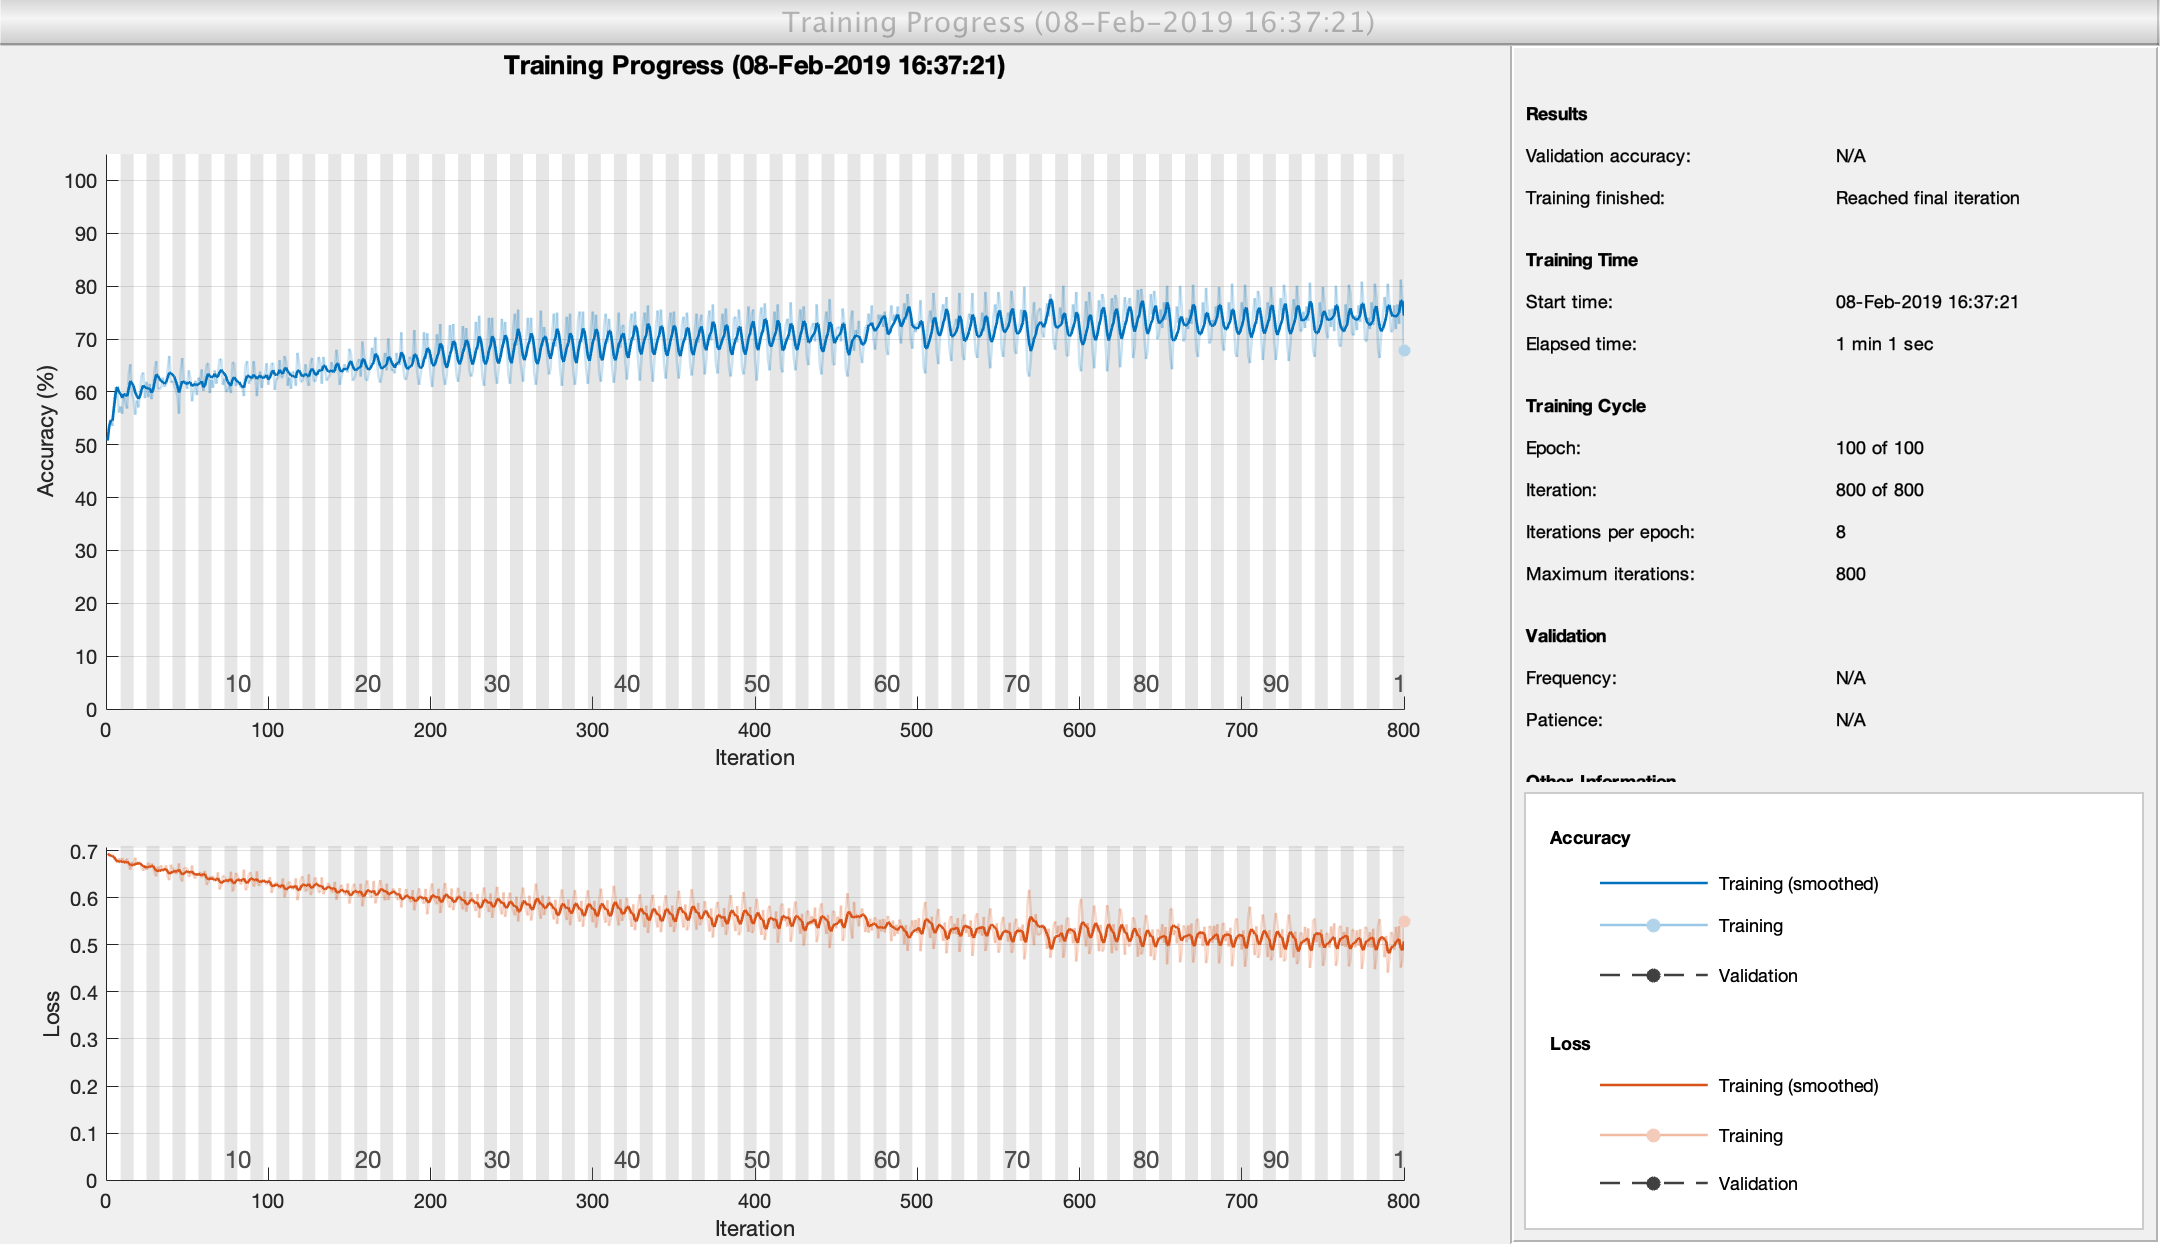

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       50.78% |       0.6931 |          0.0010 |
|       7 |          50 |       00:00:06 |       60.55% |       0.6628 |          0.0010 |
|      13 |         100 |       00:00:09 |       61.33% |       0.6313 |          0.0010 |
|      19 |         150 |       00:00:13 |       68.16% |       0.5873 |          0.0010 |
|      25 |         200 |       00:00:16 |       63.28% |       0.6161 |          0.0010 |
|      32 |         250 |       00:00:20 |       65.43% |       0.5856 |          0.0010 |
|      38 |         300 |       00:00:23 |       75.20% |       0.5475 |          0.0010 |

maxEpochs = 100;
miniBatchSize = 512;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Verbose',true, ...
    'Plots','training-progress');
net = trainNetwork(xcell_t,categorical(xresponses),layers,options);